# Optical Pumping Near Zero-Field

## Preliminary Code

clear;clc;
magBy=-10e-9 : 1e-9 : 10e-9; magBz=-200e-9 : 5e-9 : 200e-9;
sxmat = zeros(length(magBy), length(magBz));
symat = zeros(length(magBy), length(magBz));
szmat = zeros(length(magBy), length(magBz));

## Case 1

Spin polarization as a function of magnetic field Bz = -200 nT ... 200 nT, By = -10 nT ... 10 nT, and Bx = 0.

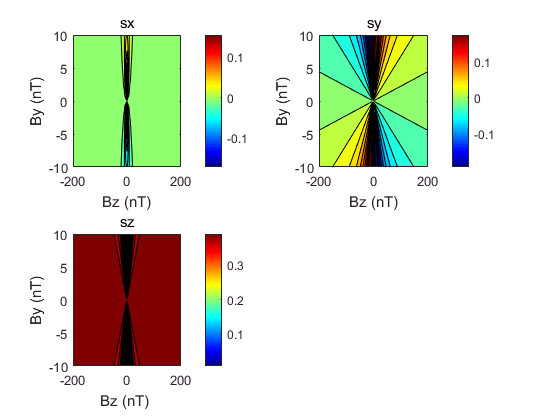

magBx=0; 
for k=1:length(magBy)
    for q=1:length(magBz)
        svect = SpinPol(magBx, magBy(k), magBz(q));
        sxmat(k,q) = svect(1);
        symat(k,q) = svect(2);
        szmat(k,q) = svect(3);
    end
end
[bz, by] = meshgrid( magBz*1e9, magBy*1e9);
figure;colormap(jet);

subplot(2, 2, 1)
contourf(bz, by, real(sxmat), 20); title('sx'); xlabel('Bz (nT)'); ylabel('By (nT)'); colorbar;
subplot(2, 2, 2)
contourf(bz, by, real(symat), 20); title('sy'); xlabel('Bz (nT)'); ylabel('By (nT)');colorbar;
subplot(2, 2, 3)
contourf(bz, by, real(szmat), 20); title('sz'); xlabel('Bz (nT) '); ylabel('By (nT)');colorbar;

## Case 2

Spin polarization as a function of magnetic field Bz = -200 nT ... 200 nT, By = -10 nT ... 10 nT, and Bx = 10 nT.

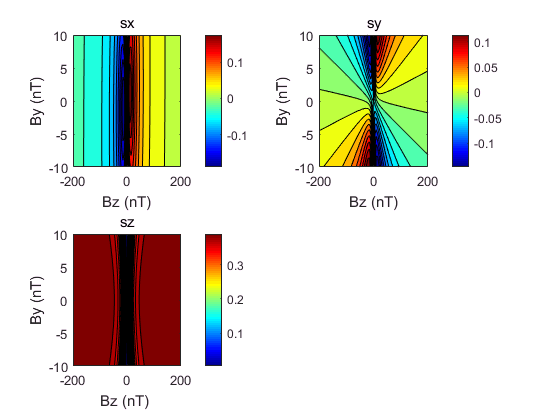

magBx=10e-9;
for k=1:length(magBy)
    for q=1:length(magBz)
        svect = SpinPol(magBx, magBy(k), magBz(q));
        sxmat(k,q) = svect(1);
        symat(k,q) = svect(2);
        szmat(k,q) = svect(3);
    end
end
[bz, by] = meshgrid( magBz*1e9, magBy*1e9);
figure;colormap(jet);

subplot(2, 2, 1)
contourf(bz, by, real(sxmat), 20); title('sx'); xlabel('Bz (nT)'); ylabel('By (nT)'); colorbar;
subplot(2, 2, 2)
contourf(bz, by, real(symat), 20); title('sy'); xlabel('Bz (nT)'); ylabel('By (nT)');colorbar;
subplot(2, 2, 3)
contourf(bz, by, real(szmat), 20); title('sz'); xlabel('Bz (nT) '); ylabel('By (nT)');colorbar;

## Define

function Svect = SpinPol(Bx, By, Bz)
    import Condition.Coil
    import Atom.AlkaliMetal 
    import Atom.Buffer.Nitrogen
    import Atom.Buffer.He4
    import Gas.VaporGas Gas.BufferGas
    import Laser.AlkaliLaserBeam
    %import CellSystem.VacuumCell
    import CellSystem.VaporCell

    coil = { ... 
        Condition.Coil('coilx', Bx), ...
        Condition.Coil('coily', By), ...
        Condition.Coil('coilz', Bz)};

    rb85=AlkaliMetal('85Rb', coil);
    rb87=AlkaliMetal('87Rb', coil);
    n2=Nitrogen();
    he4=He4();

    temperature=273.15+70;
    gases={  VaporGas(rb85, 'vapor', temperature, Atom.Transition.D1), ...
             VaporGas(rb87, 'vapor', temperature, Atom.Transition.D1) ...
             BufferGas(n2, temperature, 50*Torr2Pa, 'N2'), ...
             BufferGas(he4, temperature, 700*Torr2Pa) ...
             };

    pumpBeam_cir=AlkaliLaserBeam(100e-6, ...                     % power in [W]
                             rb87, Atom.Transition.D1, -2.25e3,...%-2.25e3, ... % ref Atom 
                             [0 0 1], [1, 1i], 4e-3);       % direction, pol, spot size

    sysApproxGS_cir=VaporCell(gases, pumpBeam_cir, 'high-pressure');

    pumpTime=1e5;
    state = sysApproxGS_cir.evolution(2, pumpTime);

    Smat = rb85.matEigen.Smat{1};
    Svect=state.meanGS(Smat);
end